clear

syms z



N_1 = 1 - z

$$N\_1 = 1-z$$

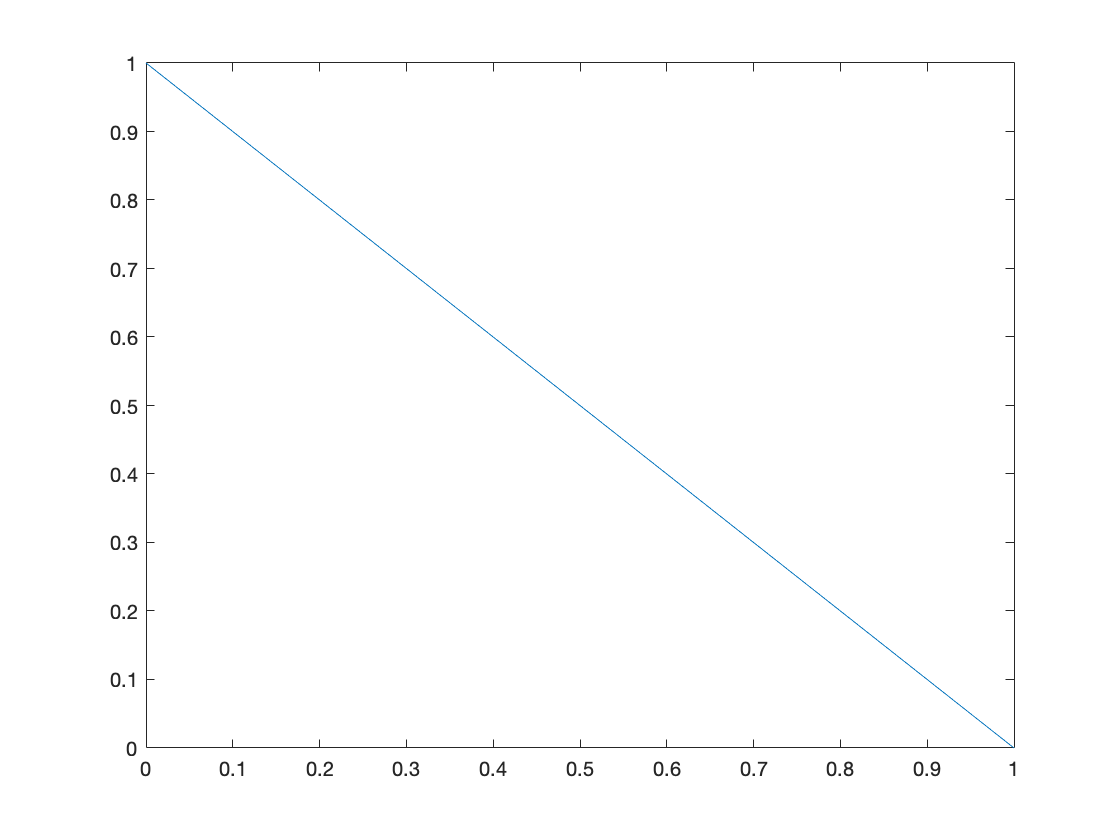

figure
fplot(N_1, [0, 1])


N_2 = z

$$N\_2 = z$$

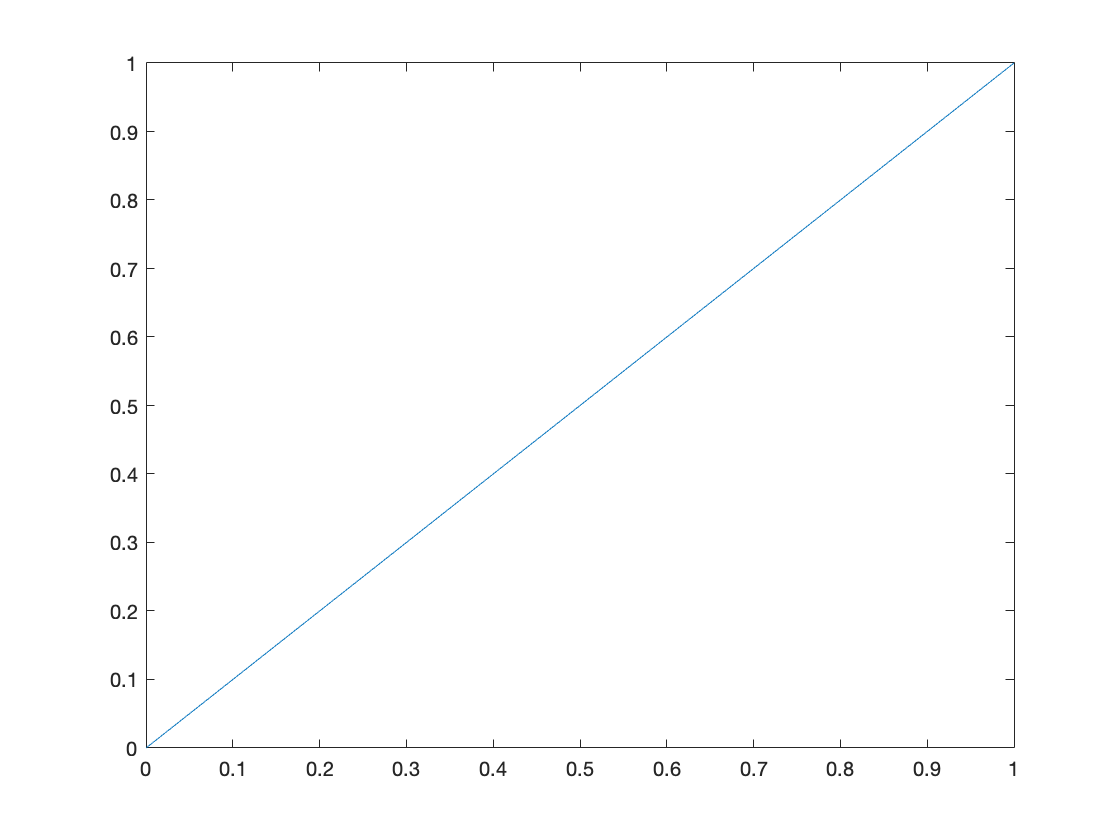

figure
fplot(N_2, [0, 1])

syms X
syms L
N_1 = subs(N_1, z, X/L)

$$N\_1 = 1-\frac{X}{L}$$

N_2 = subs(N_2, z, X/L)

$$N\_2 = \frac{X}{L}$$


N = [N_1; N_2]

$$N = \left(\begin{array}{c} 1-\frac{X}{L}\\ \frac{X}{L} \end{array}\right)$$


B = symhold('transpose(diff(N, X), X)')

$$B = \mathrm{transpose}\left(\frac{\partial }{\partial X}N,X\right)$$


B = transpose(diff(N, X))

$$B = \left(\begin{array}{cc} -\frac{1}{L} & \frac{1}{L} \end{array}\right)$$

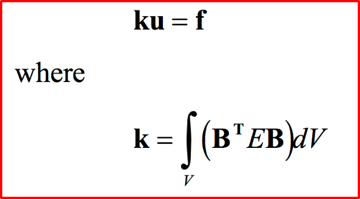

 V is  A*L

integral over V is A*integral over L

syms K
syms A
syms E
K = symhold('A*int(transpose(B)*E*B, X, 0, L)')

$$K = A\,\int B^{t}\,E\,B\mathrm{d}X$$



K = A* int(transpose(B) *E* B, X, sym(0), L)

$$K = \left(\begin{array}{cc} \frac{A\,\text{E}}{L} & -\frac{A\,\text{E}}{L}\\ -\frac{A\,\text{E}}{L} & \frac{A\,\text{E}}{L} \end{array}\right)$$

## Local Functions

## Helpers

function h = symhold(exprstring)
h = evalin(symengine, ['hold(' exprstring ' )']);
end